## [Deep Learning Neural Network](https://apmonitor.com/pds/index.php/Main/DeepLearningNeuralNetwork)

A neural network is a set of neurons (activation functions) in layers that are processed sequentially to relate an input to an output. This example implements a multi-layer perceptron (MLP) algorithm that trains using Backpropagation.

**Advantages:** Effective in nonlinear spaces where the structure of the relationship is not linear. No prior knowledge or specialized equation structure is defined although there are [**different network architectures**](https://i.stack.imgur.com/LgmYv.png) that may lead to a better result.

**Disadvantages:** Neural networks do not extrapolate well outside of the training domain. They may also require longer to train by adjusting the parameter weights to minimize a loss (objective) function. It is also more challenging to explain the outcome of the training and changes in initialization or number of epochs (iterations) may lead to different results. Too many epochs may lead to overfitting, especially if there are excess parameters beyond the minimum needed to capture the input to output relationship.

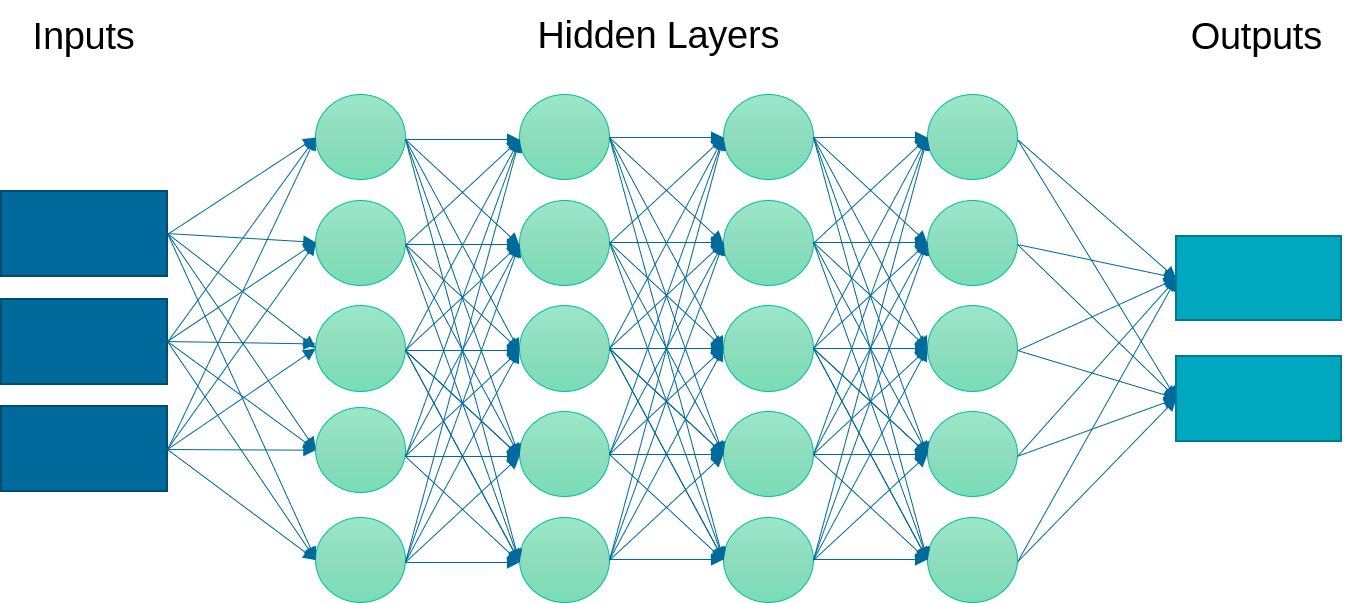

**Optical Character Recognition with Neural Network in Python**

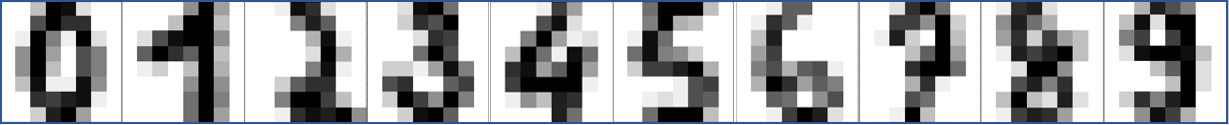

Optical character recognition (OCR) is a technology that enables the recognition of text characters in digital images. This technology can be used to automatically convert scanned documents, pictures, or other digital images that contain text into machine-readable text.

Neural networks are a type of machine learning algorithm that is often used for OCR. These algorithms are inspired by the structure and function of the human brain, and are composed of many interconnected "neurons" that process and transmit information.

In the context of OCR, a neural network can be trained to recognize text characters in images by learning from a large dataset of labeled images. The network is presented with many examples of each character, and uses these examples to learn the visual patterns that are associated with each character.

Once the network has been trained, it can be used to make predictions on new images. Given an image of a text character, the network will analyze the visual patterns in the image and make a prediction about which character is most likely to be present.

Dataset: [Data Sets for Deep Learning - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html)

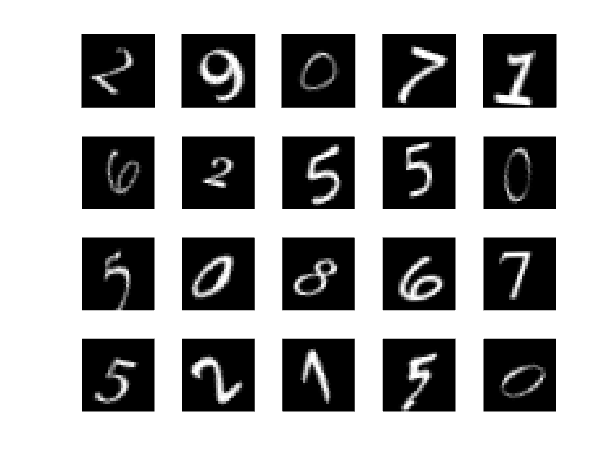

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = [];
for i = 1:n_samples
    X_data = [X_data; reshape(readimage(imds,i)',[1,28*28])];
end

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcnet(array2table(im2double(X_Train)),Y_Train);

% Evaluate the model performance on the test set
y_pred = predict(classifier,array2table(im2double(X_Test)));
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.82


Below is an example that also shows a number from the test set that is evaluated with the Neural Network.

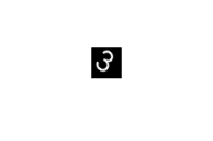

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);
figure;
imshow(imds.Files{n})

reshape(readimage(imds,n)',[1,28*28]);

% Predict number based on image
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));
disp(['Predicted:',yp])

     Predicted:      3 



**Neural Network Architectures**

There are many different types of neural network architectures, each with its own strengths and weaknesses. Some common types of neural network architectures include feedforward neural networks, convolutional neural networks, recurrent neural networks, and autoencoders.

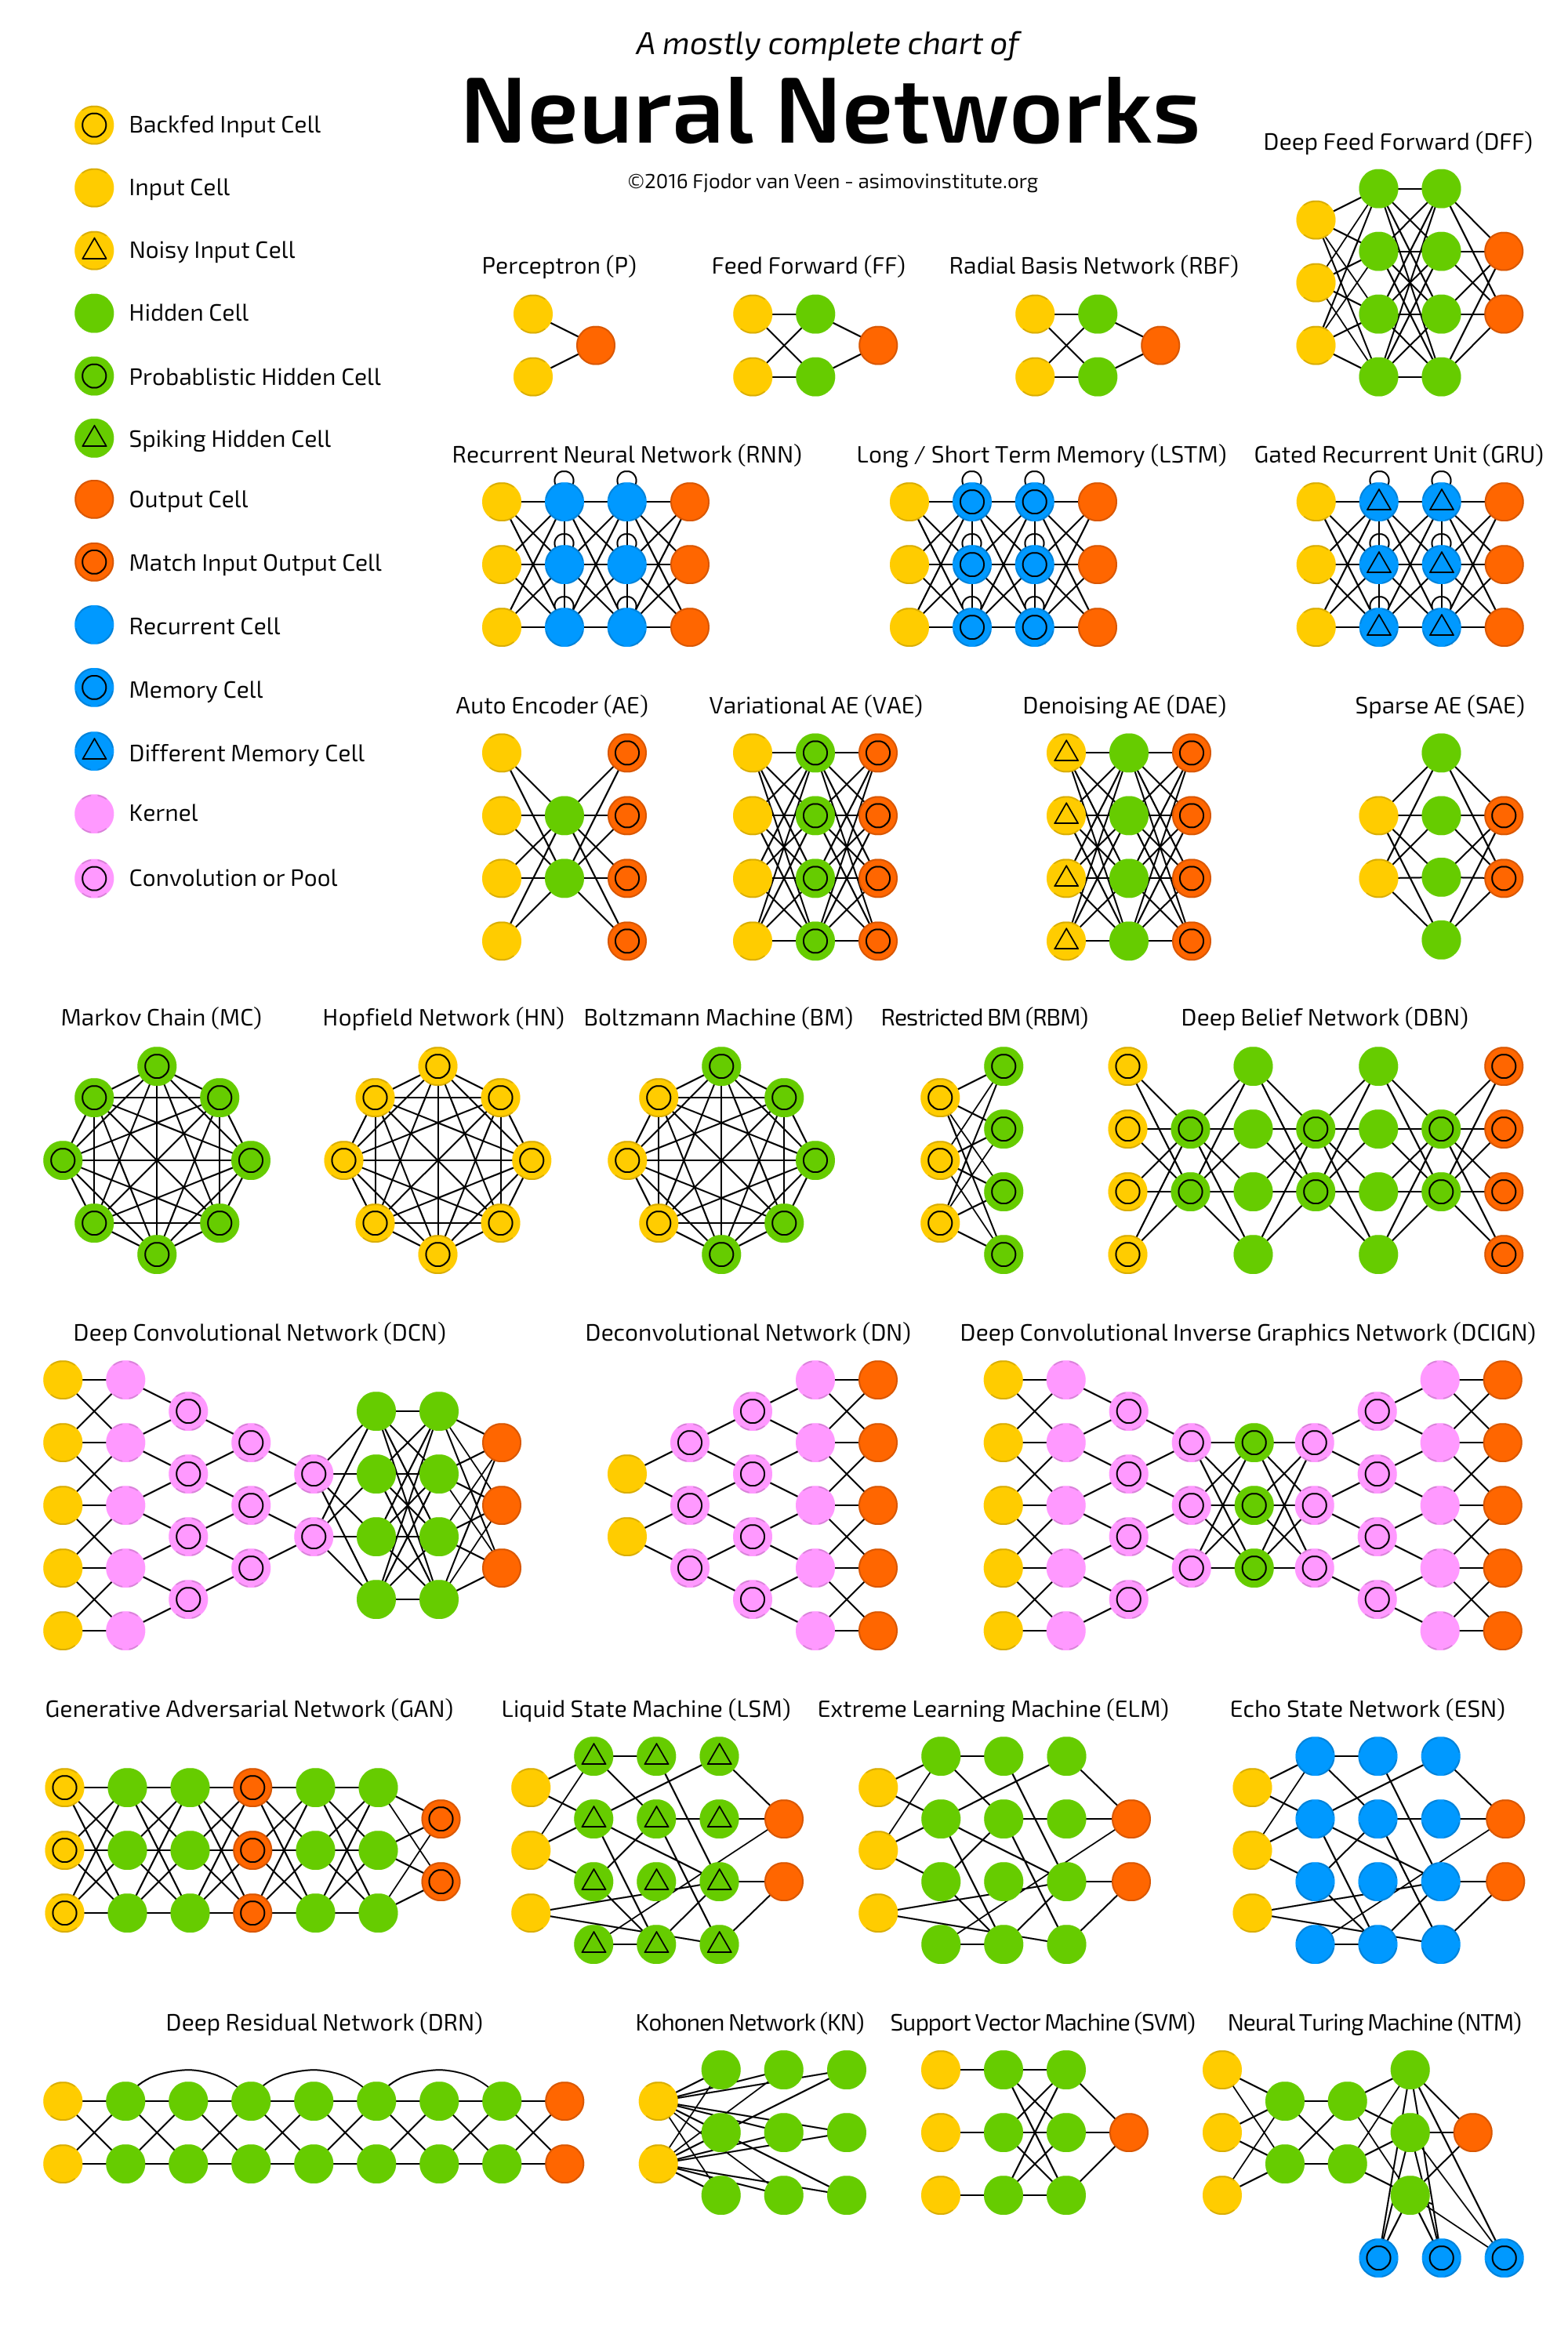

**Feedforward neural networks** are the simplest type of neural network architecture. They consist of an input layer, one or more hidden layers, and an output layer. The neurons in the input layer receive the input data, and each neuron in the hidden and output layers performs a computation based on the inputs it receives from the neurons in the previous layer. The output of the network is the result of this computation. Feedforward neural networks are commonly used for regression and classification tasks.

**Convolutional neural networks (CNNs)** are a type of neural network architecture that is specifically designed to process data that has a grid-like structure, such as an image. They consist of an input layer, one or more convolutional layers, and one or more fully-connected layers. The convolutional layers are responsible for extracting features from the input data, and the fully-connected layers are responsible for making predictions based on those features. CNNs are commonly used for image classification and other tasks that involve processing images.

**Recurrent neural networks (RNNs)** are a type of neural network architecture that is designed to process sequential data, such as time series data or natural language. They consist of an input layer, one or more hidden layers, and an output layer. The hidden layers contain "memory" cells that can retain information from previous time steps, allowing the network to make predictions based on the entire sequence of inputs. RNNs are commonly used for tasks such as language translation and speech recognition.

**Autoencoders** are a type of neural network architecture that is used for unsupervised learning. They consist of an input layer, one or more hidden layers, and an output layer. The goal of an autoencoder is to learn a compressed representation of the input data in the hidden layers, and then to use this representation to reconstruct the original input data in the output layer. Autoencoders are commonly used for dimensionality reduction and data denoising.